# **demo02 of writeMesh**

**Triangular mesh with multiple phases**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_2.mat"

load("mesh_data_2.mat")

We will see 3 variables: vert, ele, tnum

vert

vert =      5     5
     5    35
    35     5
    35    35
    45    15
    45    25
    55    15
    55    25
    65     5
    65    35


ele

ele =     28    14    53
    59    51    22
    56    35    11
    46    37     6
    44    25    35
    41    44    35
    18    25    44
    45    34    41
    41    35    43
    34    55    44


tnum

tnum =      2
     2
     1
     2
     1
     1
     1
     1
     1
     1


Check the number of phase in the mesh

length(unique(tnum))

ans = 2

## Plot mesh

Use function plotMeshes to plot mesh.

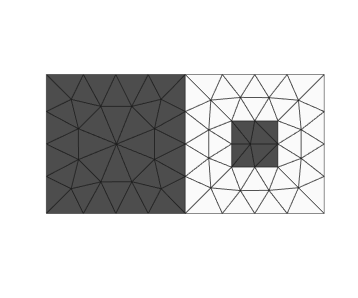

plotMeshes(vert,ele,tnum);

We saw 2 phases in the mesh.

## Export as inp file (Abaqus)

We use function printInp2d to write 2d mesh to inp file.

By default, the exported inp file would have a model with one part, which contains multiple sections. Each section corresponds to one phase in the mesh.

Please refer to demo06 to learn about format setting of inp file.

When using function printInp2d, we can specify element type, precision and file name.

ele_type = 'CPS3';
precision = 8;
file_name = 'test.inp';

printInp2d( vert, ele, tnum, ele_type, precision, file_name );

printInp2d Done! Check the inp file!


## Export as bdf file (Nastran bulk data)

We use function printBdf2d to write 2d mesh to bdf file.

precision = 8;
file_name = 'test.bdf';

printBdf2d( vert, ele, tnum, [], precision, file_name );

printBdf2d Done! Check the bdf file!


## Export as msh file (Gmsh mesh file)

We use function printMsh to write 2d mesh to msh file.

precision = 8;
file_name = 'test.msh';

printMsh( vert, ele, tnum, [], precision, file_name );

printMsh Done! Check the msh file!


When we open 'test.msh' in Gmsh, we can see 2 physical surfaces, which corresponds to 2 phases in our mesh.

BTW, we will see 3 surfaces in Gmsh. Note that, in Gmsh, surface and physical surface are different concepts. Gmsh use surfaces to define physical surface. Check Gmsh manual.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo